# BE Trottinette

clear;
clc;

## Paramètres du modèle :

%Paramètres
    %Temps
    tfinal = 20e-3;
    fT = 400;
    
    %Alim
    Ubat = 24;

    %Step
    Yc = 1.5;
    
    % G(P) :
        %T_hacheur
        Kh = 2*Ubat;    

        %T_Moteur
        R = 1;
        L = 2e-3;
        E = 0;
        tauElec = L/R;
        fElec = 1/(2*pi()*tauElec)      

fElec = 79.5775

        K0 = Kh*1/R

K0 = 48

%F(P) :
    %T_Capteur de courant
        Kc = 0.10416

Kc = 0.1042

    %Filtre ordre 2
        R5 = 5.1e3;
        R8 = 10e3;
        R12 = 10e3;
        R18 = 12e3;
        R21 = 220;
        C2 = 22e-9;
        C7 = 22e-9;
    
        Kfiltre = (R12+R18)*R8/(R12*(R5+R8))

Kfiltre = 1.4570

        tau1 = R5*R8/(R5+R8)*C2;
        tau2 = R21*C7;
        den1 = tau1+tau2;
        den2 = tau1*tau2;
        f1 = 1/(2*pi()*tau1)

f1 = 2.1419e+03

        f2 = 1/(2*pi()*tau2) 

f2 = 3.2883e+04

    %C(P) :
        %Integrateur
        f4 = (fT*sqrt(1+(fT/f1)^2) * sqrt(1+(fT/f2)^2) / (K0*Kc*Kfiltre))

f4 = 55.8661

        tau3 = tauElec

tau3 = 0.0020

        tau4 = 1/(2*pi()*f4)

tau4 = 0.0028

## Simulations

Simulation correcteur proportionnel

Yc =1.4;
sim = sim('Model_Automatique_BF_PI');

## Tracé

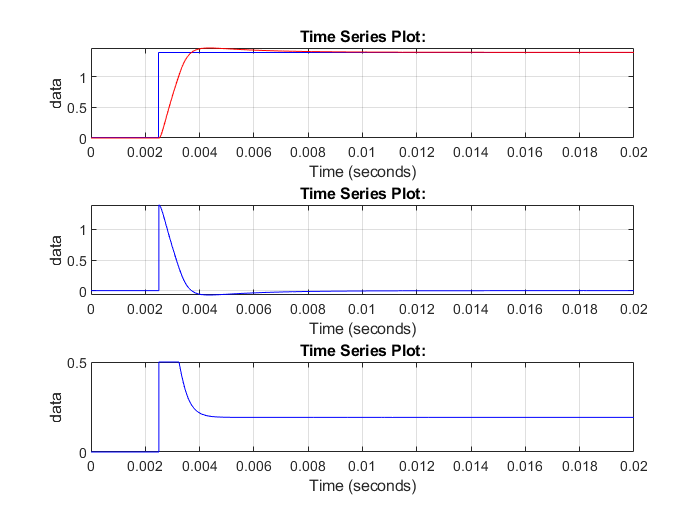

%Tracé
    subplot(3,1,1)
    %Consigne PWM
    plot(sim.Consigne,'-b');
    hold on
    %Courant capteur
    plot(sim.Vretour,'-r');
    hold off
   grid
   subplot(3,1,2)
   %Erreur
   plot(sim.Erreur,'-b');
   grid
   subplot(3,1,3)
   %Erreur
   plot(sim.sigma,'-b');
   grid

clear;
clc;

## Paramètres du modèle :

%Paramètres
    %Temps
    tfinal = 20e-3;
    fT = 400;
    
    %Alim
    Ubat = 24;

    %Step
    Yc = 1.5;
    
    % G(P) :
        %T_hacheur
        Kh = 2*Ubat;    

        %T_Moteur
        R = 1;
        L = 2e-3;
        E = 0;
        tauElec = L/R;
        fElec = 1/(2*pi()*tauElec)      

fElec = 79.5775

        K0 = Kh*1/R

K0 = 48

%F(P) :
    %T_Capteur de courant
        Kc = 0.10416

Kc = 0.1042

    %Filtre ordre 2
        R5 = 5.1e3;
        R8 = 10e3;
        R12 = 10e3;
        R18 = 12e3;
        R21 = 220;
        C2 = 22e-9;
        C7 = 22e-9;
    
        Kfiltre = (R12+R18)*R8/(R12*(R5+R8))

Kfiltre = 1.4570

        tau1 = R5*R8/(R5+R8)*C2;
        tau2 = R21*C7;
        den1 = tau1+tau2;
        den2 = tau1*tau2;
        f1 = 1/(2*pi()*tau1)

f1 = 2.1419e+03

        f2 = 1/(2*pi()*tau2) 

f2 = 3.2883e+04

    %C(P) :
        %Integrateur
        f4 = (fT*sqrt(1+(fT/f1)^2) * sqrt(1+(fT/f2)^2) / (K0*Kc*Kfiltre))

f4 = 55.8661

        tau3 = tauElec

tau3 = 0.0020

        tau4 = 1/(2*pi()*f4)

tau4 = 0.0028

T = 20e3;
sim = sim('Model_Automatique_BF_PI_enZ');

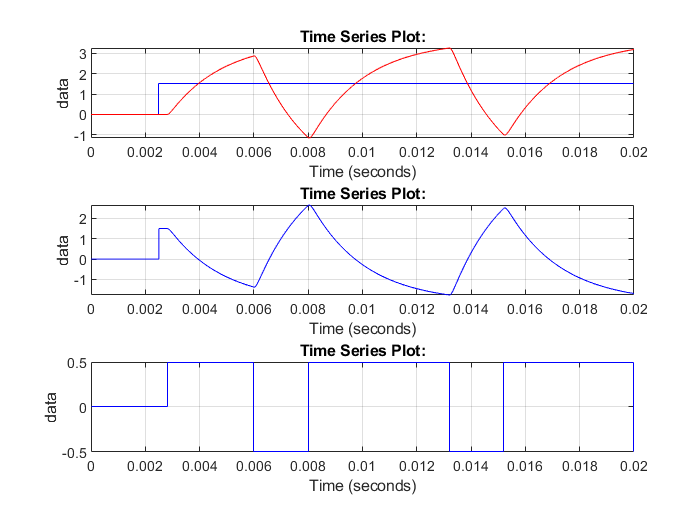

%Tracé
    subplot(3,1,1)
    %Consigne PWM
    plot(sim.Consigne,'-b');
    hold on
    %Courant capteur
    plot(sim.Vretour,'-r');
    hold off
   grid
   subplot(3,1,2)
   %Erreur
   plot(sim.Erreur,'-b');
   grid
   subplot(3,1,3)
   %Erreur
   plot(sim.sigma,'-b');
   grid